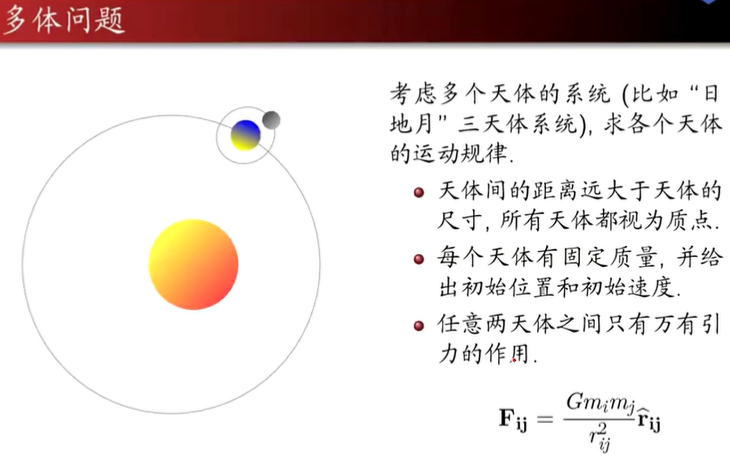

% G=6.67e-11;dt=24*3600;N=3;
% M=[sum.mass;earth.mass;moon.mass];
% R=[sun.position;earth.position;moon.position];
% V=[sum.velocity;earth.velocity;moon.velocity];
% for t=1:365
%     F=zeros(N,3);%F(i,:)=[fx,fy,fz]
%     for i=1:N%i=1->j=2,3;i=2->j=3;i=3->j无取值
%         mi=M(i);ri=R(i,:);%第i个天体的质量和位置
%         for j=(i+1):N
%             mj=M(j);rj=R(j,:);%第j个天体的质量和位置
%             rij=rj-ri;
%             fij=G*mi*mj./(norm(rij).^3).*rij;%万有引力
%             F([i,j],:)=F([i,j],:)+[fij;-fij];
%         end
%     end
%     V=V+F./repmat(M,1,3)*dt;%v(t+dt)=v(t)+a(t+dt)dt
%     R=R+V*dt;%r(t+dt)=r(t)+v(t+dt)dt
% end

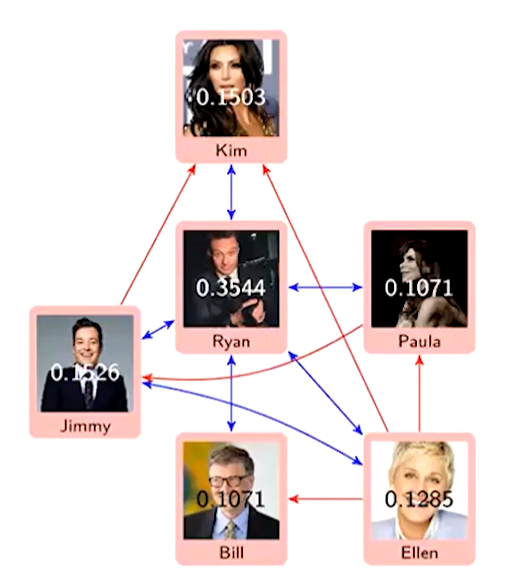

d=0.85;
n=6;
C=(1-d)/n*ones(n,1);
L=[0 1/5 0 0 0 1/5
    0 0 1/3 0 0 1/5
    0 1/5 0 0 1/2 1/5
    0 1/5 1/3 0 0 1/5
    0 1/5 0 0 0 1/5
    1 1/5 1/3 1 1/2 0];
I=eye(n);
R=(I-d*L)\C

R =     0.1071
    0.1285
    0.1526
    0.1503
    0.1071
    0.3544



$$Y=\textrm{a1}*x+\textrm{a2}$$


x=[1.0,1.5,2.0,2.5,3.0]';
y=[0.9,1.7,2.2,2.6,3.0]';
a=polyfit(x,y,1)

a =     1.0200    0.0400


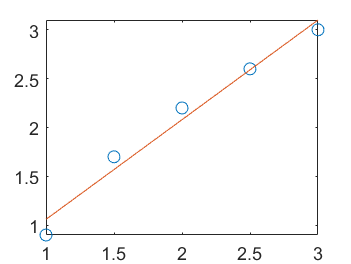

xi=1:0.1:3;
yi=polyval(a,xi);
plot(x,y,'o',xi,yi);

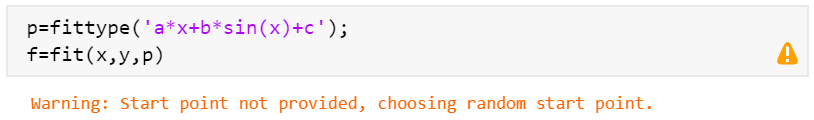

p=fittype('a*x+b*sin(x)+c','independent','x');
opt=fitoptions(p);
opt.StartPoint=[1 2 3];
f=fit(x,y,p,opt)

f =      General model:
     f(x) = a*x+b*sin(x)+c
     Coefficients (with 95% confidence bounds):
       a =       1.249  (0.9856, 1.512)
       b =      0.6357  (0.03185, 1.24)
       c =     -0.8611  (-1.773, 0.05094)

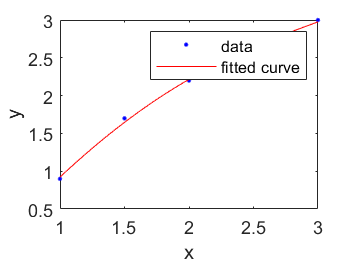

plot(f,x,y);

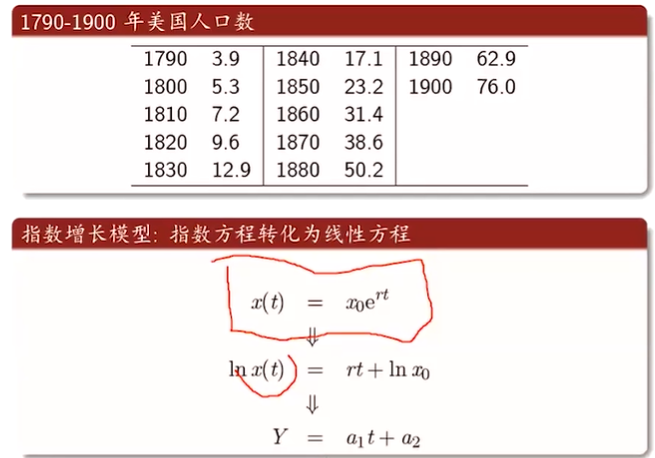

t=1790:10:1900;
p=[3.9 5.3 7.2 9.6 12.9 17.1 23.2 31.4 38.6 50.2 62.9 76.0]

p =     3.9000    5.3000    7.2000    9.6000   12.9000   17.1000   23.2000   31.4000   38.6000   50.2000   62.9000   76.0000


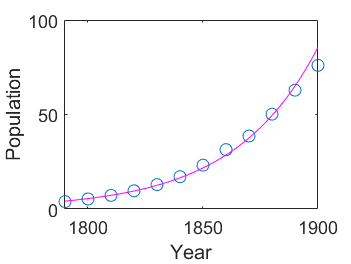

Y=log(p);X=t;
a=polyfit(X,Y,1);
x0=exp(a(2));r=a(1);
ti=1790:1900;
pti=x0*exp(r*ti);
plot(t,p,'o',ti,pti,'m')
xlabel('Year')
ylabel('Population')

f=@(t,y)cos(t);
tspan=[0,2*pi];
y0=2;
[t,y]=ode23(f,tspan,y0);

f=@(t,y)[y(2);-sin(y(1))+sin(5*t)];
tspan=[0,20];
y0=[1;0];
[t,y]=ode23(f,tspan,y0);

传染病模型

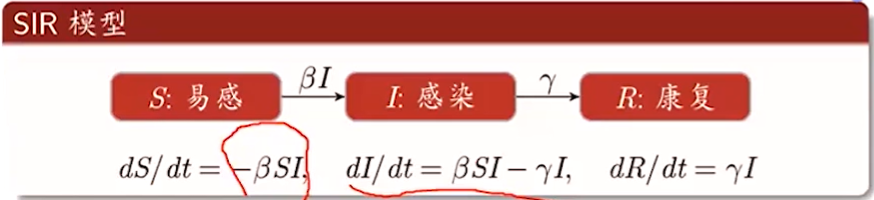

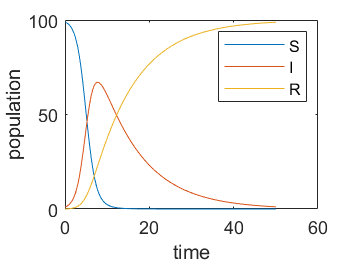

N=100;beta=0.01;gamma=0.1;
tspan=[0,50];y0=[99 1 0];
[t y]=ode45(@odesir,tspan,y0,[],beta,gamma);
plot(t,y);
xlabel('time');ylabel('population');
legend('S','I','R')

%function dy=odesir(t,y,beta,gamma)
%dy=[-beta*y(1)*y(2);
    %beta*y(1)*y(2)-gamma*y(2);
    %gamma*y(2)];
%end

知中国34个省会城市的经纬度，要求从北京出发，游遍34个城市后回到北京。用模拟退火算法求最短路径。

1.设初始解

2.产生邻解

3.定义cost函数

4.设置温度、降温

numberofcities=16;
route=randperm(numberofcities);
temperations=1000;cooling_rate=0.95;
Titerations=1;
previous_distance=totaldistance(route);

Not enough input arguments.

Error in totaldistance (line 2)
d=dis(route(end),route(1));

while temperations>1.0
    temp_route=perturb(route,'reverse')
    current_distance=totaldistance(temp_route);
    diff=current_distance-previous_distance;
    if(diff<0)||(rand<exp(-diff/(temperature)))
        route=temp_route;
        previous_distance=current_distance;
        Titerations=Titerations+1;
    end
    if Titerations>=10
        temperations=cooling_rate*temperations;
        Titerations=0;
    end
end